Import data table and convert to array

load datatable.mat
data = table2array(datatable)

data = 	1.0e+03 *

    0.0010    0.1200    0.3000    0.0020    0.1180    0.7961
    0.0010    0.1200    0.3000    0.0035    0.1180    1.4769
    0.0010    0.1200    0.3000    0.0050    0.1180    1.7975
    0.0010    0.1200    0.4000    0.0020    0.1204    0.8060
    0.0010    0.1200    0.4000    0.0035    0.1204    1.4875
    0.0010    0.1200    0.4000    0.0050    0.1205    1.8221
    0.0010    0.1200    0.5000    0.0020    0.1221    0.8606
    0.0010    0.1200    0.5000    0.0035    0.1221    1.4049
    0.0010    0.1200    0.5000    0.0050    0.1221    1.9555
    0.0010    0.1400    0.3000    0.0020    0.1398    0.8128



p = data(:,1:4)';
t = data(:,5:6)';

p1 = p(1,:);
p2 = p(2,:);
p3 = p(3,:);
p4 = p(4,:);

t1 = t(1,:);
t2 = t(2,:);

p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));

pn = [p1n p2n p3n p4n]';
tn = [t1n t2n]';

%manual mapminmax for multi-target output
%[ttnn,ttss] = mapminmax(t)
%mapminmax('reverse',ttnn,ttss)

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'poslin';

[net0,tr0] = train(net0,pn,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input


plot(mse_val0,'-');

disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    30



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.0030



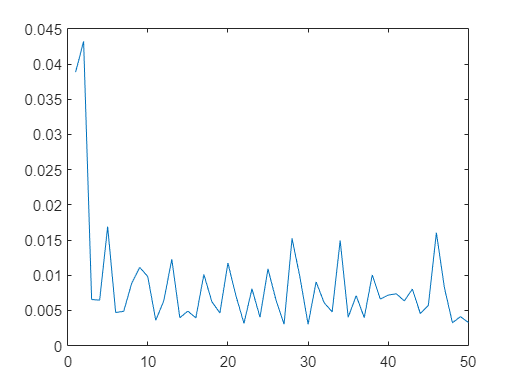

hold off;


net1 = fitnet(32,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 32
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inpu

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'tansig';

[net1,tr1] = train(net1,pn,tn);

output_ANN1 = net1(pn)

output_ANN1 =     0.6262    0.6301    0.7001    0.6294    0.6217    0.6108    0.6385    0.6464    0.6527    0.7838    0.7647    0.7736    0.8214    0.7957    0.8205    0.7916    0.7919    0.7819    0.9392    0.9081    0.9175    0.9109    0.9346    0.9400    0.9472    0.9529    0.9495    0.9925    0.9243    0.9966    0.3555    0.3660    0.3294    0.3414    0.3427    0.3403    0.4669    0.4589    0.4704    0.5182    0.5017    0.5241    0.4564    0.4517    0.4197    0.5459    0.5527    0.5492    0.6440    0.6890
    0.2018    0.4505    0.5285    0.0472    0.4339    0.6504    0.0748    0.3930    0.7309    0.0503    0.5760    0.5488    0.0313    0.4364    0.6095    0.0680    0.3993    0.7096    0.0172    0.6507    0.4964    0.0853    0.3597    0.5033    0.1491    0.3544    0.5853    0.0706    0.6141    0.5342    0.0979    0.4849    0.7041    0.1301    0.4636    0.6670    0.0667    0.5967    0.4636    0.1215    0.6959    0.4337    0.1393    0.4866    0.6580    0.0215    0.6721    0.3928    0

ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =   120.2254  120.7439  130.0321  120.6552  119.6323  118.1844  121.8610  122.9015  123.7393  141.1489  138.6027  139.7927  146.1371  142.7235  146.0158  142.1825  142.2248  140.8847  161.7634  157.6441  158.8855  158.0087  161.1646  161.8772  162.8284  163.5893  163.1323  168.8502  159.7863  169.3863   84.2945   85.6875   80.8250   82.4230   82.5898   82.2775   99.0752   98.0139   99.5435  105.8952  103.7020  106.6679   97.6867   97.0672   92.8210  109.5721  110.4651  110.0038  122.5831  128.5610


ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

ANNSEA = 	1.0e+03 *

    1.0737    1.4979    1.6309    0.8101    1.4696    1.8389    0.8572    1.3998    1.9761    0.8153    1.7120    1.6656    0.7829    1.4738    1.7691    0.8456    1.4106    1.9399    0.7589    1.8394    1.5762    0.8752    1.3431    1.5881    0.9839    1.3340    1.7279    0.8500    1.7770    1.6407    0.8965    1.5566    1.9306    0.9514    1.5204    1.8672    0.8434    1.7473    1.5202    0.9368    1.9165    1.4693    0.9671    1.5596    1.8519    0.7662    1.8759    1.3995    0.9334    1.6554


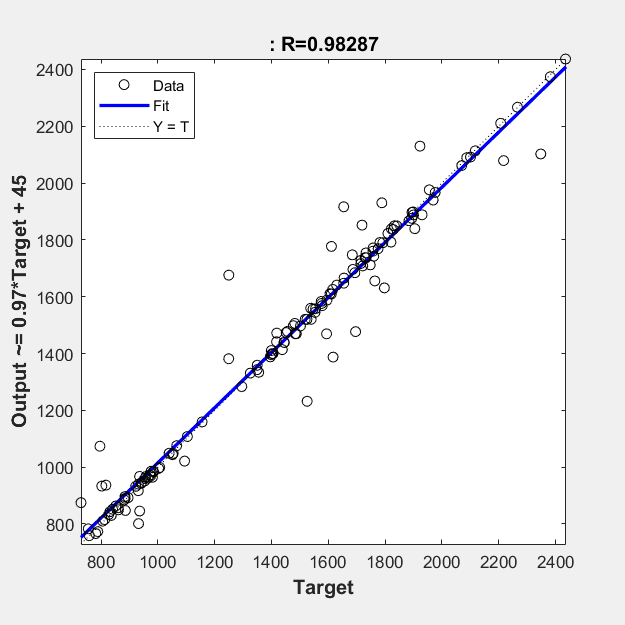

plotregression(t1,ANNIPF)
plotregression(t2,ANNSEA)

% plotregression(t1n,output_ANN1(1,:));
% plotregression(t2n,output_ANN1(2,:));


pred = net1([0.75 0.75 0.75 0.75]')

pred =     0.2286
    0.3111



IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 67.4575

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

SEA = 1.2602e+03


maxipf=max(data(:,5))

maxipf = 169.8391

minipf=min(data(:,5))

minipf = 37.1100

maxsea=max(data(:,6))

maxsea = 2.4352e+03

minsea=min(data(:,6))

minsea = 729.5885

%     compet - Competitive transfer function.
%     elliotsig - Elliot sigmoid transfer function.
%     hardlim - Positive hard limit transfer function.
%     hardlims - Symmetric hard limit transfer function.
%     logsig - Logarithmic sigmoid transfer function.
%     netinv - Inverse transfer function.
%     poslin - Positive linear transfer function.
%     purelin - Linear transfer function.
%     radbas - Radial basis transfer function.
%     radbasn - Radial basis normalized transfer function.
%     satlin - Positive saturating linear transfer function.
%     satlins - Symmetric saturating linear transfer function.
%     softmax - Soft max transfer function.
%     tansig - Symmetric sigmoid transfer function.
%     tribas - Triangular basis transfer function.